# Chemical Reactor

## Task 1

The concentration over time of a chemical in a reactor is given by the differential equation:

dC/dt=2t−1/2t^2

In the partially completed script `chemReactor.mlx`, this ODE has been implemented in the local function `reactor`. 

In this interaction, you will complete the script to determine the chemical concentration from t=0 to t=4, with an initial concentration C(0)=0.

Task

Determine the chemical concentration over time and plot the result by completing the following steps:

1. Create a variable `tRange` to define the time interval over which to solve from t=0 to t=4.

2. Create a variable `C0` to define the initial concentration, C(0)=0.

3. Use `ode45` to solve the differential equation, which has been implemented for you in the local function `reactor`. Assign the result to the output variables `tSol` and `CSol`.

4. Plot the concentration `CSol` as a function of `tSol`.

1.  Define the time interval.

tRange=[0 4]

tRange =      0     4


2.  Define the initial condition.

C0=0

C0 = 0

3.  Call the `ode45` function to solve the ODE.

[tSol, CSol]=ode45(@reactor,tRange,C0)

tSol =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


CSol =          0
    0.0098
    0.0387
    0.0855
    0.1493
    0.2292
    0.3240
    0.4328
    0.5547
    0.6885


4.  Plot the solution.

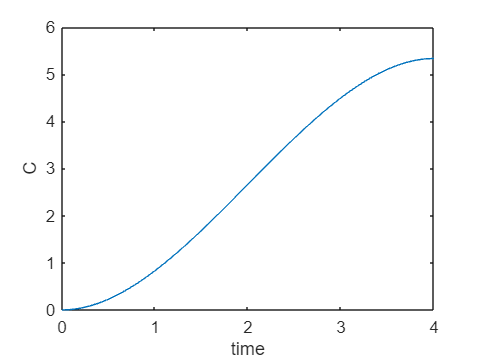

plot(tSol,CSol)

% Annotate the plot
xlabel("time")
ylabel("C")

## Further Practice

The exact solution for the concentration is 

C=t2−1/6t3. Add the exact solution to your previous plot to see how well they agree.

`tExact` `=` `linspace``(``0``,``4``,``20``)``;`

`CExact` `=` `tExact``.^``2` `-` `1``/``6``*``tExact``.^``3``;`

`hold` `on`

`plot``(``tExact``,``CExact``,``"r:o"``)`

`hold` `off`

`legend``(``"ode45"``,``"exact"``,``"Location"``,``"northwest"``)`

What's the maximum concentration between t=0 and t=4?

`maxC` `=` `max``(``CSol``)`

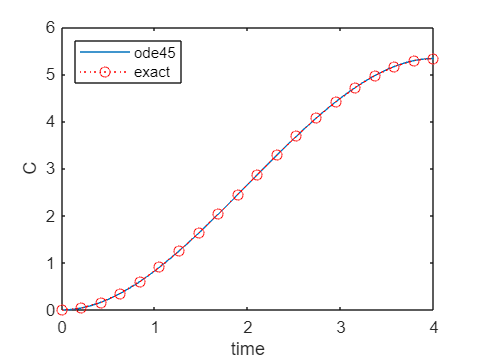

tExact = linspace(0,4,20);
CExact = tExact.^2 - 1/6*tExact.^3;
hold on
plot(tExact,CExact,"r:o")
hold off
legend("ode45","exact","Location","northwest")

maxC = max(CSol)

maxC = 5.3333

Do not edit. This code defines the ODE function to solve the ODE  .

function dCdt = reactor(t,C)
% Define dCdt:
dCdt = 2*t - 1/2*t.^2;
end